clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[3.87;-6.69;-7.76];
u31=[0;0;1];
r2=[-7.73;0;0];
u32=[0;0;1];
r3=[3.87;6.69;7.76];
u33=[0;0;1];
r4=[-7.73;0;-11.81];
u34=[0;0;-1];
r5=[3.87;6.69;-4.05];
u35=[0;0;-1];
r6=[3.87;-6.69;3.70];
u36=[0;0;-1];

% center and direction of spheroids

axis([4 15 4 15]);
for R3=5:0.2:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    hold on
    scatter(R1,R3,'b')
    xlabel('R1'); ylabel('R3');
end

ans =    10.6000    5.0000    1.0012


ans =    10.0500    5.2000    1.0006


ans =     9.6000    5.4000    1.0027


ans =     9.2500    5.6000    1.0040


ans =     9.0000    5.8000    1.0010


ans =     8.7500    6.0000    1.0037


ans =     8.5500    6.2000    1.0049


ans =     8.4000    6.4000    1.0029


ans =     8.2500    6.6000    1.0042


ans =     8.1500    6.8000    1.0005


ans =     8.0000    7.0000    1.0077


ans =     7.9000    7.2000    1.0087


ans =     7.8500    7.4000    1.0024


ans =     7.7500    7.6000    1.0070


ans =     7.7000    7.8000    1.0035


ans =     7.6500    8.0000    1.0012


ans =     7.6000    8.2000    1.0000


ans =     7.5000    8.4000    1.0103


ans =     7.5000    8.6000    1.0005


ans =     7.4500    8.8000    1.0021


ans =     7.4000    9.0000    1.0045


ans =     7.3500    9.2000    1.0077


ans =     7.3500    9.4000    1.0002


ans =     7.3000    9.6000    1.0046


ans =     7.2500    9.8000    1.0096


ans =     7.2500   10.0000    1.0034


ans =     7.2000   10.2000    1.0095


ans =     7.2000   10.4000    1.0039


ans =     7.1500   10.6000    1.0109


ans =     7.1500   10.8000    1.0060


ans =     7.1500   11.0000    1.0013


ans =     7.1000   11.2000    1.0093


ans =     7.1000   11.4000    1.0051


ans =     7.1000   11.6000    1.0012


ans =     7.0500   11.8000    1.0101


ans =     7.0500   12.0000    1.0065


ans =     7.0500   12.2000    1.0031


ans =     7.0000   12.4000    1.0128


ans =     7.0000   12.6000    1.0097


ans =     7.0000   12.8000    1.0068


ans =     7.0000   13.0000    1.0040


ans =     7.0000   13.2000    1.0013


ans =     6.9500   13.4000    1.0119


ans =     6.9500   13.6000    1.0095


ans =     6.9500   13.8000    1.0071


ans =     6.9500   14.0000    1.0049


ans =     6.9500   14.2000    1.0027


ans =     6.9500   14.4000    1.0007


ans =     6.9000   14.6000    1.0122


ans =     6.9000   14.8000    1.0103


ans = 1×3
    6.9000   15.0000    1.0085



for R1=5:0.2:15 %离心率
    R3=5.6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r4,R1,R3,u32,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    [R1,R3,miu2]
 
    scatter(R1,R3,'r')
    xlabel('R1'); ylabel('R3');
end

ans = 1×3
    5.0000    5.9000    1.0017


ans = 1×3
    5.2000    5.9000    1.0017


ans = 1×3
    5.4000    5.9000    1.0017


ans = 1×3
    5.6000    5.9000    1.0017


ans = 1×3
    5.8000    5.9000    1.0017


ans = 1×3
    6.0000    5.9000    1.0017


ans = 1×3
    6.2000    5.9000    1.0017


ans = 1×3
    6.4000    5.9000    1.0017


ans = 1×3
    6.6000    5.9000    1.0017


ans = 1×3
    6.8000    5.9000    1.0017


ans = 1×3
    7.0000    5.9000    1.0017


ans = 1×3
    7.2000    5.9000    1.0017


ans = 1×3
    7.4000    5.9000    1.0017


ans = 1×3
    7.6000    5.9000    1.0017


ans = 1×3
    7.8000    5.9000    1.0017


ans = 1×3
    8.0000    5.9000    1.0017


ans = 1×3
    8.2000    5.9000    1.0017


ans = 1×3
    8.4000    5.9000    1.0017


ans = 1×3
    8.6000    5.9000    1.0017


ans = 1×3
    8.8000    5.9000    1.0017


ans = 1×3
    9.0000    5.9000    1.0017


ans = 1×3
    9.2000    5.9000    1.0017


ans = 1×3
    9.4000    5.9000    1.0017


ans = 1×3
    9.6000    5.9000    1.0017


ans = 1×3
    9.8000    5.9000    1.0017


ans = 1×3
   10.0000    5.9000    1.0017


ans = 1×3
   10.2000    5.9000    1.0017


ans = 1×3
   10.4000    5.9000    1.0017


ans = 1×3
   10.6000    5.9000    1.0017


ans = 1×3
   10.8000    5.9000    1.0017


ans = 1×3
   11.0000    5.9000    1.0017


ans = 1×3
   11.2000    5.9000    1.0017


ans = 1×3
   11.4000    5.9000    1.0017


ans = 1×3
   11.6000    5.9000    1.0017


ans = 1×3
   11.8000    5.9000    1.0017


ans = 1×3
   12.0000    5.9000    1.0017


ans = 1×3
   12.2000    5.9000    1.0017


ans = 1×3
   12.4000    5.9000    1.0017


ans = 1×3
   12.6000    5.9000    1.0017


ans = 1×3
   12.8000    5.9000    1.0017


ans = 1×3
   13.0000    5.9000    1.0017


ans = 1×3
   13.2000    5.9000    1.0017


ans = 1×3
   13.4000    5.9000    1.0017


ans = 1×3
   13.6000    5.9000    1.0017


ans = 1×3
   13.8000    5.9000    1.0017


ans = 1×3
   14.0000    5.9000    1.0017


ans = 1×3
   14.2000    5.9000    1.0017


ans = 1×3
   14.4000    5.9000    1.0017


ans = 1×3
   14.6000    5.9000    1.0017


ans = 1×3
   14.8000    5.9000    1.0017


ans = 1×3
   15.0000    5.9000    1.0017



for R1=5:0.2:15 %离心率
    R3=5.6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
 
    scatter(R1,R3,'cyan')
    xlabel('R1'); ylabel('R3');
end

ans = 1×3
    5.0000    5.7000    1.0106


ans = 1×3
    5.2000    5.7000    1.0106


ans = 1×3
    5.4000    5.7000    1.0106


ans = 1×3
    5.6000    5.7000    1.0106


ans = 1×3
    5.8000    5.7000    1.0106


ans = 1×3
    6.0000    5.7000    1.0106


ans = 1×3
    6.2000    5.7000    1.0106


ans = 1×3
    6.4000    5.7000    1.0106


ans = 1×3
    6.6000    5.7000    1.0106


ans = 1×3
    6.8000    5.7000    1.0106


ans = 1×3
    7.0000    5.7000    1.0106


ans = 1×3
    7.2000    5.7000    1.0106


ans = 1×3
    7.4000    5.7000    1.0106


ans = 1×3
    7.6000    5.7000    1.0106


ans = 1×3
    7.8000    5.7000    1.0106


ans = 1×3
    8.0000    5.7000    1.0106


ans = 1×3
    8.2000    5.7000    1.0106


ans = 1×3
    8.4000    5.7000    1.0106


ans = 1×3
    8.6000    5.7000    1.0106


ans = 1×3
    8.8000    5.7000    1.0106


ans = 1×3
    9.0000    5.7000    1.0106


ans = 1×3
    9.2000    5.7000    1.0106


ans = 1×3
    9.4000    5.7000    1.0106


ans = 1×3
    9.6000    5.7000    1.0106


ans = 1×3
    9.8000    5.7000    1.0106


ans = 1×3
   10.0000    5.7000    1.0106


ans = 1×3
   10.2000    5.7000    1.0106


ans = 1×3
   10.4000    5.7000    1.0106


ans = 1×3
   10.6000    5.7000    1.0106


ans = 1×3
   10.8000    5.7000    1.0106


ans = 1×3
   11.0000    5.7000    1.0106


ans = 1×3
   11.2000    5.7000    1.0106


ans = 1×3
   11.4000    5.7000    1.0106


ans = 1×3
   11.6000    5.7000    1.0106


ans = 1×3
   11.8000    5.7000    1.0106


ans = 1×3
   12.0000    5.7000    1.0106


ans = 1×3
   12.2000    5.7000    1.0106


ans = 1×3
   12.4000    5.7000    1.0106


ans = 1×3
   12.6000    5.7000    1.0106


ans = 1×3
   12.8000    5.7000    1.0106


ans = 1×3
   13.0000    5.7000    1.0106


ans = 1×3
   13.2000    5.7000    1.0106


ans = 1×3
   13.4000    5.7000    1.0106


ans = 1×3
   13.6000    5.7000    1.0106


ans = 1×3
   13.8000    5.7000    1.0106


ans = 1×3
   14.0000    5.7000    1.0106


ans = 1×3
   14.2000    5.7000    1.0106


ans = 1×3
   14.4000    5.7000    1.0106


ans = 1×3
   14.6000    5.7000    1.0106


ans = 1×3
   14.8000    5.7000    1.0106


ans = 1×3
   15.0000    5.7000    1.0106



for R3=5:0.2:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r6,R1,R3,u32,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r6,R1,R3,u32,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r6,R1,R3,u32,u36);
    end
    [R1,R3,miu2]

    scatter(R1,R3,'magenta')
    xlabel('R1'); ylabel('R3');
end

ans = 1×3
    7.2000    5.0000    1.0017


ans = 1×3
    7.1500    5.2000    1.0035


ans = 1×3
    7.1000    5.4000    1.0067


ans = 1×3
    7.0500    5.6000    1.0111


ans = 1×3
    7.0500    5.8000    1.0037


ans = 1×3
    7.0000    6.0000    1.0099


ans = 1×3
    7.0000    6.2000    1.0039


ans = 1×3
    6.9500    6.4000    1.0116


ans = 1×3
    6.9500    6.6000    1.0067


ans = 1×3
    6.9500    6.8000    1.0021


ans = 1×3
    6.9000    7.0000    1.0114


ans = 1×3
    6.9000    7.2000    1.0076


ans = 1×3
    6.9000    7.4000    1.0041


ans = 1×3
    6.9000    7.6000    1.0008


ans = 1×3
    6.8500    7.8000    1.0116


ans = 1×3
    6.8500    8.0000    1.0089


ans = 1×3
    6.8500    8.2000    1.0063


ans = 1×3
    6.8500    8.4000    1.0039


ans = 1×3
    6.8500    8.6000    1.0017


ans = 1×3
    6.8000    8.8000    1.0137


ans = 1×3
    6.8000    9.0000    1.0117


ans = 1×3
    6.8000    9.2000    1.0099


ans = 1×3
    6.8000    9.4000    1.0082


ans = 1×3
    6.8000    9.6000    1.0066


ans = 1×3
    6.8000    9.8000    1.0051


ans = 1×3
    6.8000   10.0000    1.0037


ans = 1×3
    6.8000   10.2000    1.0024


ans = 1×3
    6.8000   10.4000    1.0011


ans = 1×3
    6.7500   10.6000    1.0144


ans = 1×3
    6.7500   10.8000    1.0132


ans = 1×3
    6.7500   11.0000    1.0122


ans = 1×3
    6.7500   11.2000    1.0112


ans = 1×3
    6.7500   11.4000    1.0102


ans = 1×3
    6.7500   11.6000    1.0093


ans = 1×3
    6.7500   11.8000    1.0085


ans = 1×3
    6.7500   12.0000    1.0077


ans = 1×3
    6.7500   12.2000    1.0069


ans = 1×3
    6.7500   12.4000    1.0062


ans = 1×3
    6.7500   12.6000    1.0055


ans = 1×3
    6.7500   12.8000    1.0048


ans = 1×3
    6.7500   13.0000    1.0042


ans = 1×3
    6.7500   13.2000    1.0035


ans = 1×3
    6.7500   13.4000    1.0030


ans = 1×3
    6.7500   13.6000    1.0024


ans = 1×3
    6.7500   13.8000    1.0019


ans = 1×3
    6.7500   14.0000    1.0014


ans = 1×3
    6.7500   14.2000    1.0009


ans = 1×3
    6.7500   14.4000    1.0004


ans = 1×3
    6.7000   14.6000    1.0147


ans = 1×3
    6.7000   14.8000    1.0143


ans = 1×3
    6.7000   15.0000    1.0139


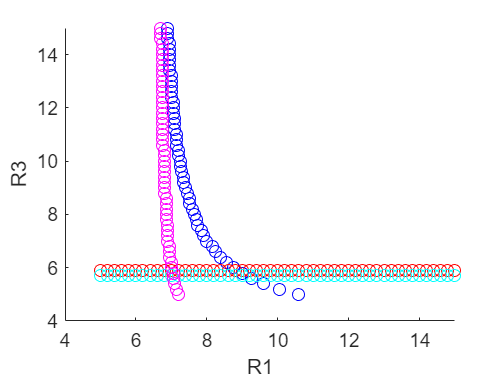


hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end


